# Slosh 3D - Tilting about y

Different parametrization of the pendulum

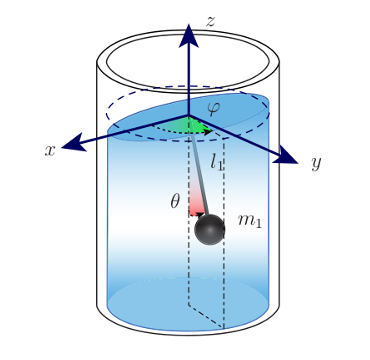

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 3D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

A rotation about the axis y of the container is imposed.

clc 
clear all

syms theta(t) phi(t) gamma(t) beta(t)
syms t 
syms h l m g b d
syms x(t) y(t) z(t) 

$\theta$ = second rotation about Y describing the sloshing

$\phi$ = first rotation abouy Z describing the plane of sloshing

l = length of pendulum

m = mass of pendulum

h = height of the liquid

b = damping coefficient

$\beta$  = imposed angle of rotation about y

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

Use of the parametrization using 3-2-3 euler angle convention. Note: to have the mass lying in the positive quadrant (x and y positive) the second rotation about y is taken in the opposite direction.

### Homogeneous Transformation from inertial frame to pivot

% First rotation about z
% R_z_gamma = [cos(gamma),  -sin(gamma), 0;
%            sin(gamma),   cos(gamma), 0;
%            0,          0,        1];

% Second rotation about y
R_y_beta = [cos(-beta),  0,  sin(-beta);
              0,            1,            0;
             -sin(-beta),  0,  cos(-beta)];

R = R_y_beta;

Define translation vector

p = [x(t); y(t); z(t)];

Define the transformation

T_wc = [R, p; 0 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_wc);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & 0 & -\sin\left(\beta \left(t\right)\right) & x\left(t\right)\\ 0 & 1 & 0 & y\left(t\right)\\ \sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from inertial frame to pivot

% First rotation about z
R_z_phi = [cos(phi),  -sin(phi), 0;
           sin(phi),   cos(phi), 0;
           0,          0,        1];

% Second rotation about y
R_y_theta = [cos(-theta),  0,  sin(-theta);
              0,            1,            0;
             -sin(-theta),  0,  cos(-theta)];

% Third rotation about z
R_z_phi_minus = [cos(-phi),  -sin(-phi), 0;
               sin(-phi),   cos(-phi), 0;
               0,          0,        1];

R = R_z_phi * R_y_theta %* R_z_phi_minus

$$R(t) = \left(\begin{array}{ccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [0; 0; d];

d from pivot to center of rotation, in the case of CoR = CoM, d = -h/2

Define the transformation

T_cp = [R, p; 0 0 0 1];
T_cp = formula(T_cp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_cp);

$$\left(\begin{array}{cccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$p_m =$$

$$\left(\begin{array}{c}
l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\\
l\,\sin \left(\phi \left(t\right)\right)\sin \left(\theta \left(t\right)\right)\\
-l\,\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; 0; -l];

Homogeneous transformation

T_pm = [eye(3), p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wc*T_cp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)+l\,\left(\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)$$

Coordinates of pendulum mass relative to the pivot

xr = l*cos(phi)*sin(theta)

$$xr(t) = l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

yr = l*sin(phi)*sin(theta)

$$yr(t) = l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zr = -l*cos(theta)

$$zr(t) = -l\,\cos\left(\theta \left(t\right)\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-\frac{\partial }{\partial t}x\left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;

### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2

$$v2(t) = {\left(l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


D = b/2 *(v2);

D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equation of motion

#### Theta

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,l^2\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l^2\,m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)+\frac{l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{4}-\frac{l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \phi \left(t\right)\right)}^2}{2}-d\,l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+l\,m\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-\frac{l^2\,m\,\cos\left(2\,\phi \left(t\right)\right)\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{4}+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\


syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot beta_dot beta_ddot
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, beta_dot^2, beta_ddot, phi_dot^2, phi_ddot, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\frac{l\,m\,s_{\beta }\,s_{\theta }-c_{\beta }\,c_{\varphi }\,c_{\theta }\,l\,m}{l^{2}\,m}\,\ddot{x}+\left(-\frac{c_{\theta }\,s_{\varphi }}{l}\right)\,\ddot{y}+\left(-\frac{c_{\beta }\,l\,m\,s_{\theta }+c_{\varphi }\,c_{\theta }\,l\,m\,s_{\beta }}{l^{2}\,m}\right)\,\ddot{z}+\left(-\frac{c_{\beta }\,l\,m\,s_{\theta }+c_{\varphi }\,c_{\theta }\,l\,m\,s_{\beta }}{l^{2}\,m}\right)\,g+\frac{d\,l\,m\,s_{\theta }-\frac{l^{2}\,m\,\sin\left(2\,\theta \left(t\right)\right)}{4}+\frac{l^{2}\,m\,\cos\left(2\,\varphi \left(t\right)\right)\,\sin\left(2\,\theta \left(t\right)\right)}{4}}{l^{2}\,m}\,{\dot{\beta }}^{2}+\left(-\frac{c_{\varphi }\,l^{2}\,m-c_{\varphi }\,c_{\theta }\,d\,l\,m}{l^{2}\,m}\right)\,\ddot{\beta }+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\varphi }}^{2}+\left(-\frac{b}{m}\right)\,\dot{\theta }+\frac{\dot{\beta }\,l^{2}\,m\,\dot{\varphi }\,s_{\varphi }-\dot{\beta }\,l^{2}\,m\,\dot{\varphi }\,s_{\varphi }\,\cos\left(2\,\theta \left(t\right)\right)}{l^{2}\,m}$$

disp(latex(eqn1));

\ddot{\theta }=\frac{l\,m\,s_{\beta }\,s_{\theta }-c_{\beta }\,c_{\phi }\,c_{\theta }\,l\,m}{l^2\,m}\,\ddot{x}+\left(-\frac{c_{\theta }\,s_{\phi }}{l}\right)\,\ddot{y}+\left(-\frac{c_{\beta }\,l\,m\,s_{\theta }+c_{\phi }\,c_{\theta }\,l\,m\,s_{\beta }}{l^2\,m}\right)\,\ddot{z}+\left(-\frac{c_{\beta }\,l\,m\,s_{\theta }+c_{\phi }\,c_{\theta }\,l\,m\,s_{\beta }}{l^2\,m}\right)\,g+\frac{d\,l\,m\,s_{\theta }-\frac{l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)}{4}+\frac{l^2\,m\,\cos\left(2\,\phi \left(t\right)\right)\,\sin\left(2\,\theta \left(t\right)\right)}{4}}{l^2\,m}\,{\dot{\beta }}^2+\left(-\frac{c_{\phi }\,l^2\,m-c_{\phi }\,c_{\theta }\,d\,l\,m}{l^2\,m}\right)\,\ddot{\beta }+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\phi }}^2+\left(-\frac{b}{m}\right)\,\dot{\theta }+\frac{\dot{\beta }\,l^2\,m\,\dot{\phi }\,s_{\phi }-\dot{\beta }\,l^2\,m\,\dot{\phi }\,s_{\phi }\,\cos\left(2\,\theta \left(t\right)\right)}{l^2\,m}



$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} +\frac{1}{l_n }\,\left(s_{\beta } \,s_{\theta } -c_{\beta } \,c_{\phi } \,c_{\theta } \,\right)\,\ddot{x} -\frac{1}{l_n }c_{\theta } \,s_{\phi } \,\ddot{y} -\frac{1}{l_n }\left(c_{\beta } \,s_{\theta } +c_{\phi } \,c_{\theta } \,s_{\beta } \right)\,\left(g+\ddot{z} \right)+\frac{1}{l_n }s_{\theta \;} \left(d-\frac{1}{2}l_n c_{\theta \;} +\frac{1}{2}l_n \;\cos \left(2\phi \right)s_{\theta } c_{\theta } \right){\dot{\beta} }^2 -\frac{1}{l_n }c_{\phi } \left(l_n -c_{\theta } \,d\right)\ddot{\beta} +{\;s}_{\theta \;} c_{\theta \;} {\dot{\phi} }^2 +\dot{\beta} \,\dot{\phi} \,s_{\phi } \left(1-\cos \left(2\,\theta \right)\right)\,$$


#### Phi

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

-l\,\left(l\,m\,{\cos\left(\theta \left(t\right)\right)}^2\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)-b\,l\,\frac{\partial }{\partial t} \phi \left(t\right)-l\,m\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+b\,l\,{\cos\left(\theta \left(t\right)\right)}^2\,\frac{\partial }{\partial t} \phi \left(t\right)-m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-\frac{l\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{2}+m\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-d\,m\,\sin\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)+g\,m\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right


syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot beta_dot beta_ddot
eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, beta_dot^2, beta_ddot, phi_dot^2, phi_ddot, theta_dot]);

disp(eqn2);

$$\ddot{\varphi }=\frac{c_{\beta }\,m\,s_{\varphi }\,s_{\theta }}{l\,m-{c_{\theta }}^{2}\,l\,m}\,\ddot{x}+\left(-\frac{c_{\varphi }\,m\,s_{\theta }}{l\,m-{c_{\theta }}^{2}\,l\,m}\right)\,\ddot{y}+\frac{m\,s_{\beta }\,s_{\varphi }\,s_{\theta }}{l\,m-{c_{\theta }}^{2}\,l\,m}\,\ddot{z}+\frac{m\,s_{\beta }\,s_{\varphi }\,s_{\theta }}{l\,m-{c_{\theta }}^{2}\,l\,m}\,g+\left(-\frac{\frac{l\,m\,\sin\left(2\,\varphi \left(t\right)\right)}{2}-c_{\varphi }\,{c_{\theta }}^{2}\,l\,m\,s_{\varphi }}{l\,m-{c_{\theta }}^{2}\,l\,m}\right)\,{\dot{\beta }}^{2}+\left(-\frac{d\,m\,s_{\varphi }\,s_{\theta }-c_{\theta }\,l\,m\,s_{\varphi }\,s_{\theta }}{l\,m-{c_{\theta }}^{2}\,l\,m}\right)\,\ddot{\beta }+\left(-\frac{-2\,\dot{\beta }\,l\,m\,s_{\varphi }\,{c_{\theta }}^{2}+2\,\dot{\beta }\,l\,m\,s_{\varphi }+l\,m\,\dot{\varphi }\,\sin\left(2\,\theta \left(t\right)\right)}{l\,m-{c_{\theta }}^{2}\,l\,m}\right)\,\dot{\theta }-\frac{b\,l\,\dot{\varphi }-b\,{c_{\theta }}^{2}\,l\,\dot{\varphi }}{l\,m-{c_{\theta }}^{2}\,l\,m}$$

disp(latex(eqn2));

\ddot{\phi }=\frac{c_{\beta }\,m\,s_{\phi }\,s_{\theta }}{l\,m-{c_{\theta }}^2\,l\,m}\,\ddot{x}+\left(-\frac{c_{\phi }\,m\,s_{\theta }}{l\,m-{c_{\theta }}^2\,l\,m}\right)\,\ddot{y}+\frac{m\,s_{\beta }\,s_{\phi }\,s_{\theta }}{l\,m-{c_{\theta }}^2\,l\,m}\,\ddot{z}+\frac{m\,s_{\beta }\,s_{\phi }\,s_{\theta }}{l\,m-{c_{\theta }}^2\,l\,m}\,g+\left(-\frac{\frac{l\,m\,\sin\left(2\,\phi \left(t\right)\right)}{2}-c_{\phi }\,{c_{\theta }}^2\,l\,m\,s_{\phi }}{l\,m-{c_{\theta }}^2\,l\,m}\right)\,{\dot{\beta }}^2+\left(-\frac{d\,m\,s_{\phi }\,s_{\theta }-c_{\theta }\,l\,m\,s_{\phi }\,s_{\theta }}{l\,m-{c_{\theta }}^2\,l\,m}\right)\,\ddot{\beta }+\left(-\frac{-2\,\dot{\beta }\,l\,m\,s_{\phi }\,{c_{\theta }}^2+2\,\dot{\beta }\,l\,m\,s_{\phi }+l\,m\,\dot{\phi }\,\sin\left(2\,\theta \left(t\right)\right)}{l\,m-{c_{\theta }}^2\,l\,m}\right)\,\dot{\theta }-\frac{b\,l\,\dot{\phi }-b\,{c_{\theta }}^2\,l\,\dot{\phi }}{l\,m-{c_{\theta }}^2\,l\,m}



$$\ddot{\phi} \;\left(1-{c_{\theta } }^2 \right)=-\frac{b}{m}\left(1-{c_{\theta } }^2 \right)\,\dot{\phi} +\frac{1}{l_n }c_{\beta } \,s_{\phi } \,s_{\theta } \,\ddot{x} -\frac{1}{l_n }c_{\phi } \,s_{\theta } \,\ddot{y} +\frac{1}{l_n }s_{\beta } \,s_{\phi } \,s_{\theta } \,\left(g+\ddot{z} \right)\;-\left(s_{\phi } c_{\phi } \left(1-{c_{\theta } }^2 \right)\right)\,{\dot{\beta} }^2 +\frac{1}{l_n }s_{\phi } \,s_{\theta } \left(l_n \;c_{\theta } -d\right)\,\ddot{\beta} -2\dot{\beta} \,s_{\phi } \left(1-{c_{\theta } }^2 \right)\,\dot{\theta} -2\;\dot{\theta} \dot{\phi} \,s_{\theta } c_{\theta }$$



$$U=\;\frac{1}{l_n }s_{\theta } \left(s_{\phi } \left(c_{\beta } \,\ddot{x} +s_{\beta } \,\left(g+\ddot{z} \right)\right)-c_{\phi } \,\ddot{y} \right)$$
